# TP3

## Pre

clear
close all

## Pre2

%----------numeric param pour discrétiser---
SPstep=1;
PVstep=1;
ElecStorageStep=5;
HWStorageStep=25;
%-------------Param---------------
%the unit costs
costSP=400;
costPV=500;
costElecStorage=180;
costHWStorage=50;
%alpha, beta and gamma for hot water and elec
betaH=350;
alphaH=35;
gammaH=10^-3;
betaE=120;
alphaE=12;
gammaE=5*10^-3;

%target values
targetElec=4000;
targetHW=20000;
targetCost=100000;

%-----------Desision variables---------
SPArea=1:SPstep:200

SPArea =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


PVArea=1:PVstep:200

PVArea =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


elecStorage=1:ElecStorageStep:targetCost/costElecStorage %ça sert à rien d'aller trop loin

elecStorage =      1     6    11    16    21    26    31    36    41    46    51    56    61    66    71    76    81    86    91    96   101   106   111   116   121   126   131   136   141   146   151   156   161   166   171   176   181   186   191   196   201   206   211   216   221   226   231   236   241   246


HWStorage=1:HWStorageStep:targetCost/costHWStorage 

HWStorage =            1          26          51          76         101         126         151         176         201         226         251         276         301         326         351         376         401         426         451         476         501         526         551         576         601         626         651         676         701         726         751         776         801         826         851         876         901         926         951         976        1001        1026        1051        1076        1101        1126        1151        1176        1201        1226


Q = Qo + (Qlim − Qo)(1 −e−γ St )

Qlim = β Sp

Qo = α S

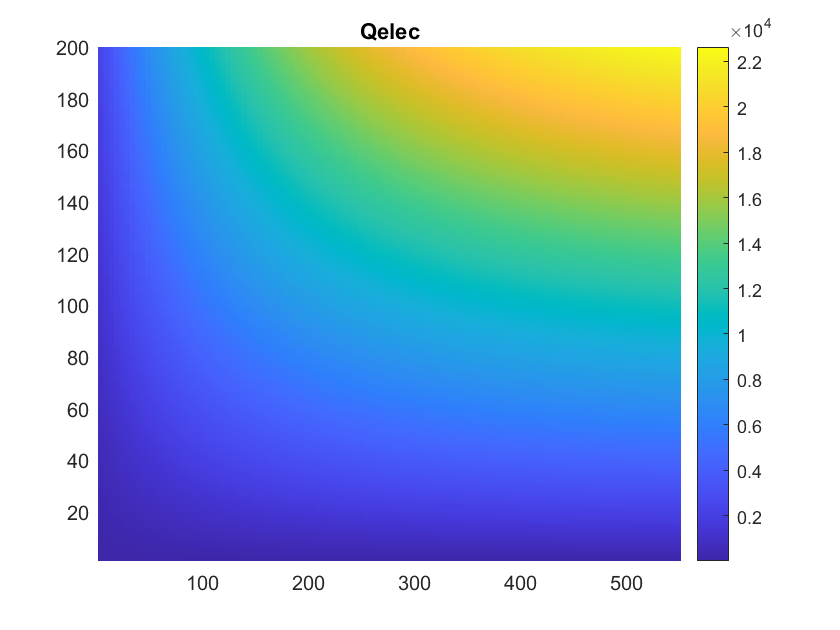

for i=1:length(PVArea)
    for j=1:length(elecStorage)
        costElec(i,j)=costPV*PVArea(i)+costElecStorage*elecStorage(j);
        Qlim=betaE*PVArea(i);
        Qo=alphaE*PVArea(i);
        Qelec(i,j)=Qo+(Qlim-Qo)*(1-exp(-gammaE*elecStorage(j)));
    end
end

figure(1)
pcolor(elecStorage,PVArea,Qelec)
title('Qelec')
colorbar
shading flat %remove black edge

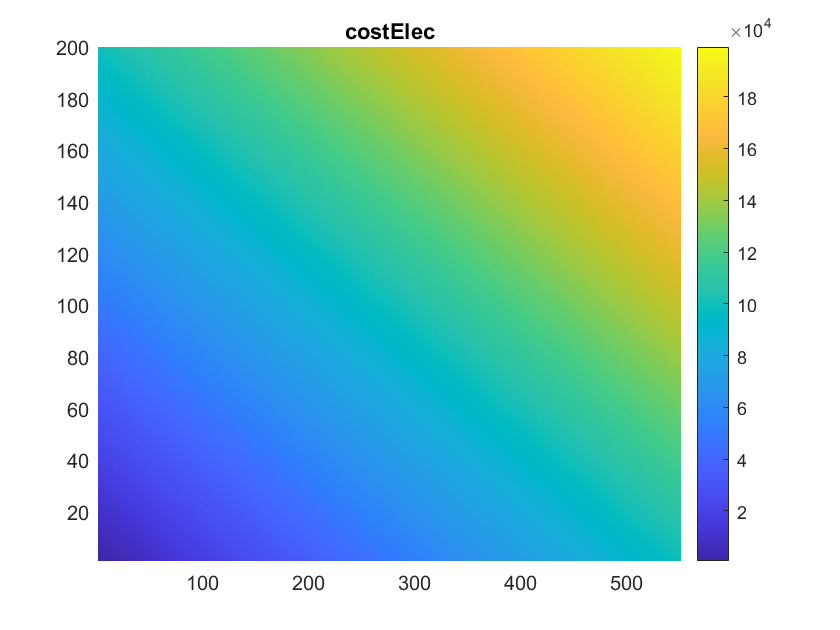


figure(2)
pcolor(elecStorage,PVArea,costElec )
title('costElec')
colorbar
shading flat

## Q1

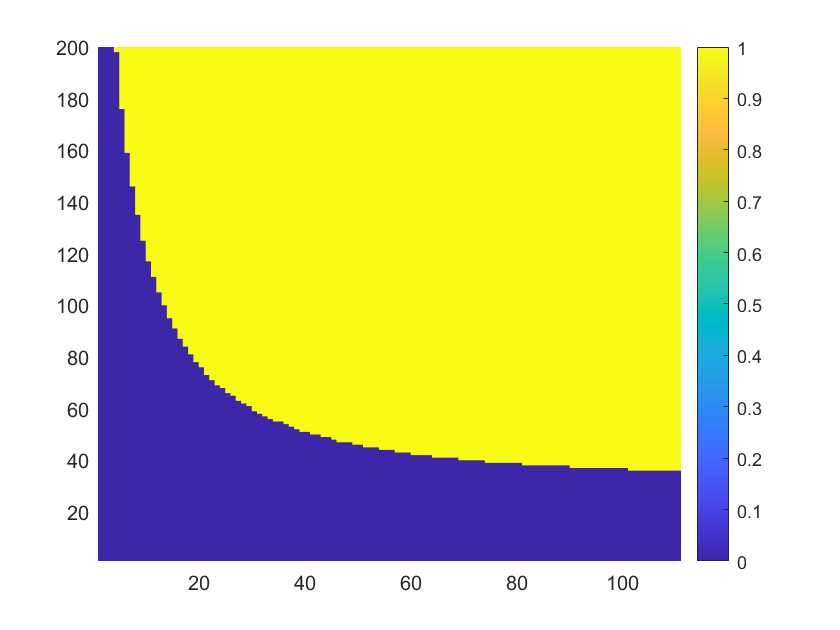

% determine for which values of battery, the production goal is acheived
figure(3)
pcolor(Qelec>=4000)
shading flat
colorbar

`!!! important !!!` new thing !!!

% select the costs associated with the acceptable values of Qelec
costElec(Qelec>=4000)

ans =       101880
      102380
      102880
       91780
       92280
       92780
       93280
       93780
       94280
       94780


%list of costElec which meet the goal of Qelec

必须要两个相同大小的矩阵，当Qelec大于四千时，costElec的对应值

相当于取出当Qelec大于四千时的indice，再把indice放进costElec中。

%identify the min cost associated with the acceptable values of Qelec
tmp=min(costElec(Qelec>=4000))

tmp = 54480

disp(['The min cost to meet elec goal is ',num2str(tmp),'€'])

The min cost to meet elec goal is 54480€


## Q2 just cold water

Q = Qo + (Qlim − Qo)(1 −e−γ St )

Qlim = β Sp

Qo = α S

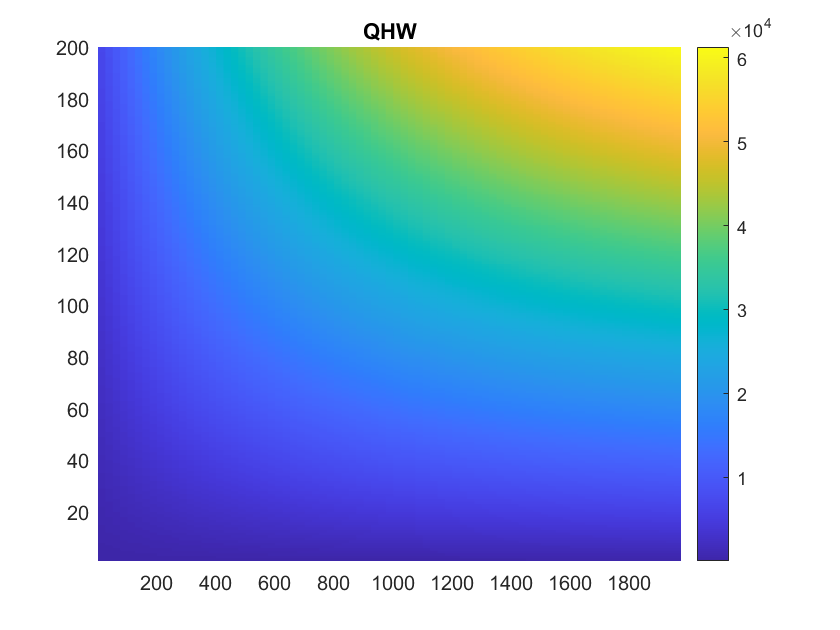

%with SPArea and HWStorage
for i=1:length(SPArea)
    for j=1:length(HWStorage)
        costHW(i,j)=costSP*SPArea(i)+costHWStorage*HWStorage(j);
        Qlim=betaH*SPArea(i);
        Qo=alphaH*SPArea(i);
        QHW(i,j)=Qo+(Qlim-Qo)*(1-exp(-gammaH*HWStorage(j)));
    end
end
figure(4)
pcolor(HWStorage,SPArea,QHW)
title('QHW')
colorbar
shading flat %remove black edge

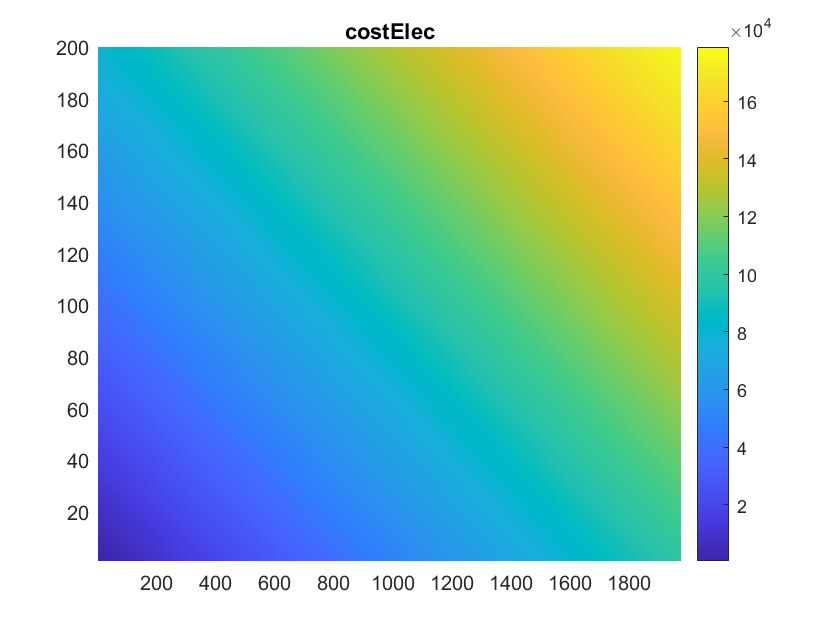

figure(5)
pcolor(HWStorage,SPArea,costHW)
title('costElec')
colorbar
shading flat %remove black edge

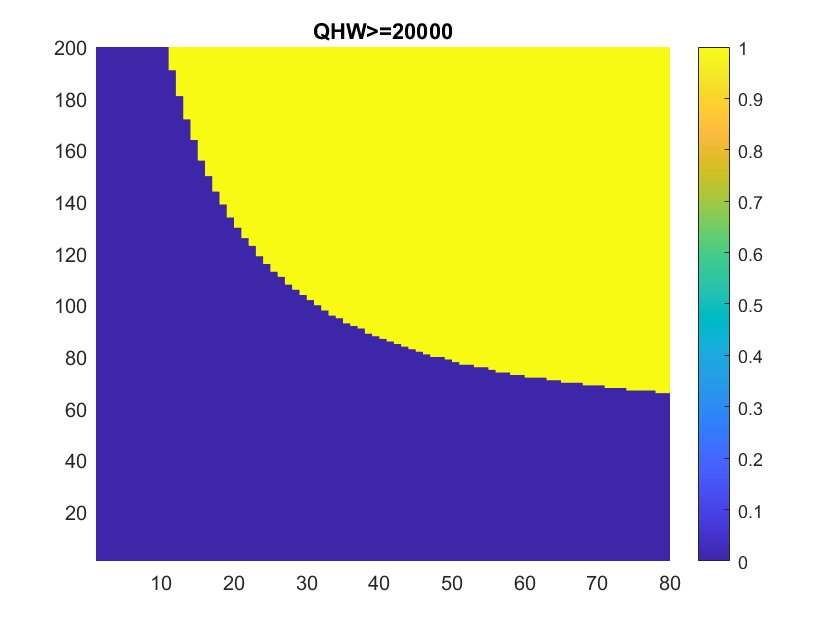

%QHW which are acceptable
figure(6)
pcolor(QHW>=20000)
title('QHW>=20000')
colorbar
shading flat

%list of costHW associated
costHW(QHW>=20000)

ans =        88950
       89350
       89750
       90150
       90550
       90950
       91350
       91750
       92150
       92550


%and find the min cost
tmp=min(costHW(QHW>=20000));
disp(['The min cost of cold water which meet the goal is ',num2str(tmp),'€'])

The min cost of cold water which meet the goal is 75150€


ans = 	1.0e+04 *

    1.3376
    1.8467
    2.0045
    1.8927
    1.5753
    1.1016
    0.5100


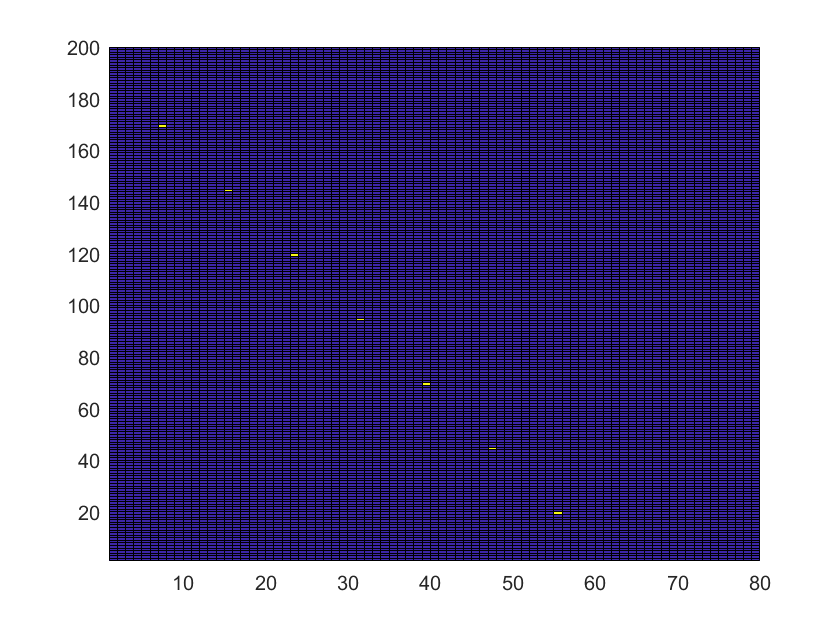

QHW(costHW==tmp)%the kwh corresponding to 75150€

## Q3

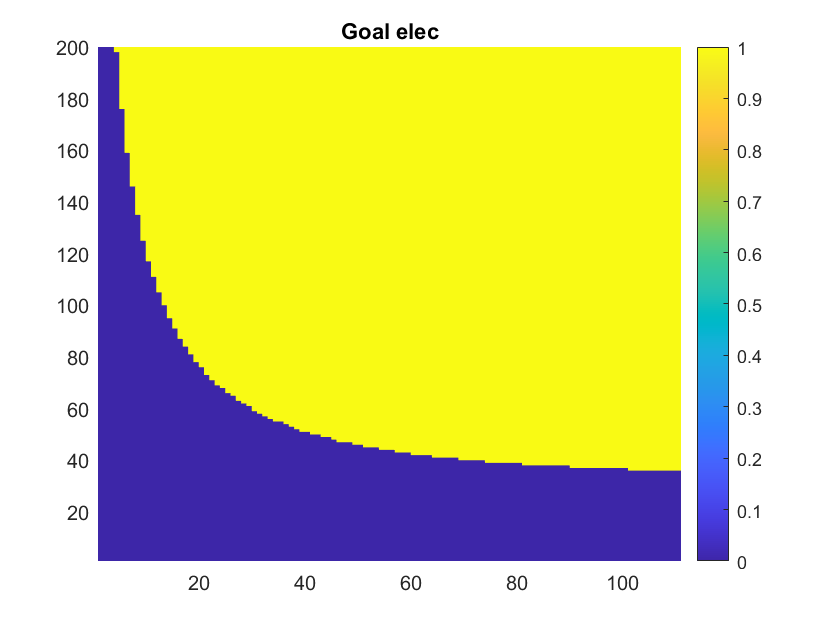

%make a graph of elec goals
figure(7)
pcolor(Qelec>=4000)
title('Goal elec')
shading flat
colorbar

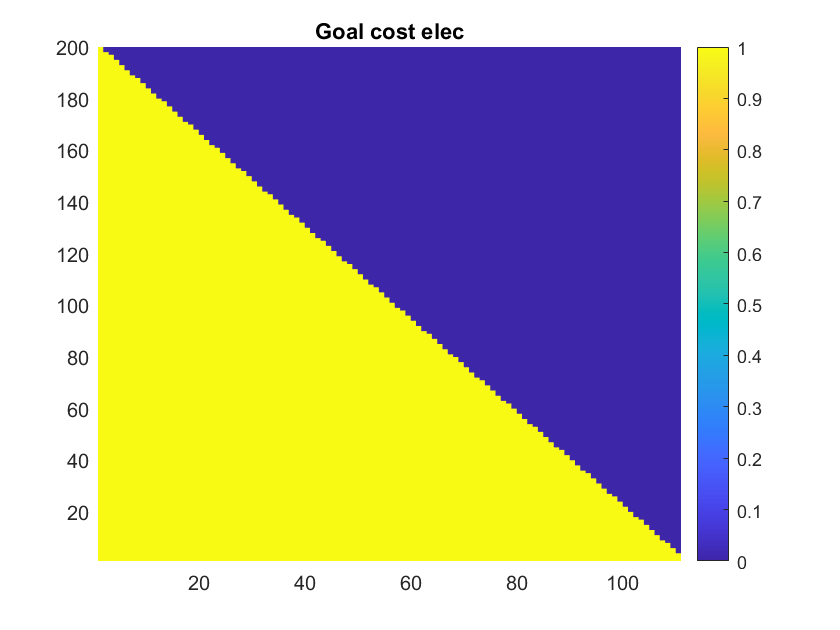


figure(8)
pcolor(costElec<=100000)
title('Goal cost elec')
shading flat
colorbar

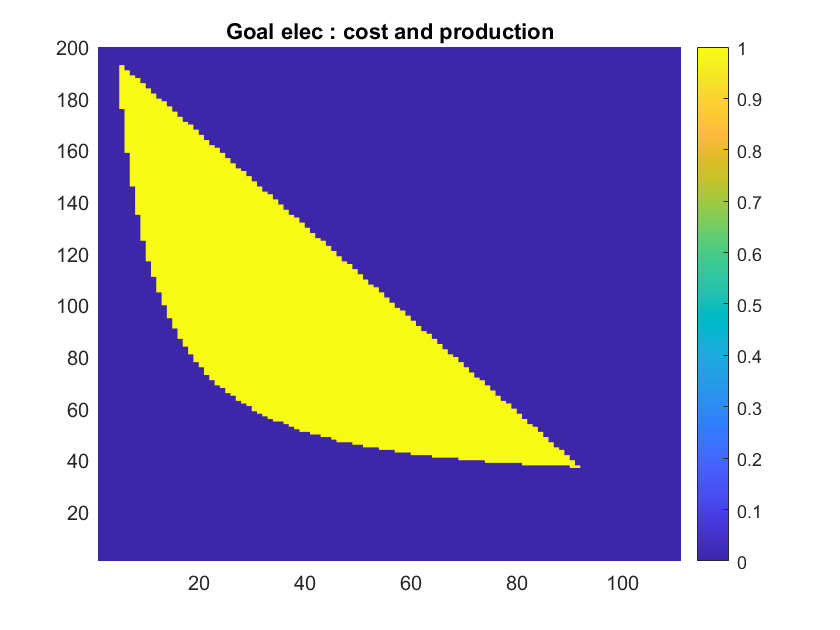


figure(9)
pcolor((Qelec>=4000)&(costElec<=100000))
title('Goal elec : cost and production')
shading flat
colorbar

based on the result of Q1 

the yellow part of figure7 is when the production is acceptable

the yellow part of figure8 is when the cost is acceptable

the figure9 is an "and" of figure7 and figure8

`!!!``the importance is`** to** use the expression

of pcolor(...logical expression...) it will give binary variables (just 1 and 0)

## q4 & q5

we have three goals to acheive :

1) cost

2) elec

3) cold water

it is possible to meet 1

it is possible to meet 2

it is possible to meet 1 + 2

but it is **not** possible to meet 1 + 2 + 3

we should achieve 1 2 and minimise failure with respect to 3

*solution :*

*spend 59980€ + produce ____ elec*

*or spend 45520€ + produce ___ cold water*

## own

ctrl+enter the section pre2

% ----------objective fct----------
costElec=costPV*PVArea+costElecStorage*elecStorage'
costHW=costSP*SPArea+costHWStorage*HWStorage'
%matrix 4 dimensions
% dim1 PVArea
% dim2 elecStorage
% dim3 SPArea
% dim4 HWStorage
cost=zeros(length(PVArea),length(elecStorage),length(SPArea),length(HWStorage));



## Test